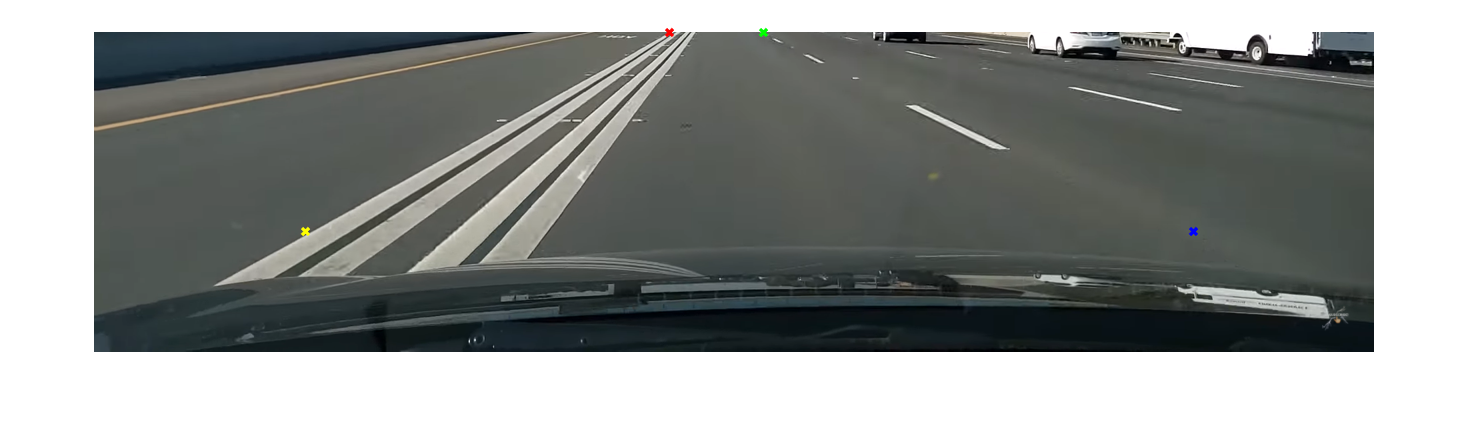

img = imread("test_imgs\img2.png");

hd_resolution = [720 1280];
img = imresize(img, hd_resolution);

% Cutting image
img = img(401:end,:,:);
imshow(img); hold on;

% These are the arbitrarily selected points in the image
pa = [576 1]';
pb = [670 1]';
pc = [1100 200]';
pd = [212 200]';

plot(pa(1),pa(2),'x','LineWidth',2,'Color','red');

plot(pb(1),pb(2),'x','LineWidth',2,'Color','green');

plot(pc(1),pc(2),'x','LineWidth',2,'Color','blue');

plot(pd(1),pd(2),'x','LineWidth',2,'Color','yellow');
hold off

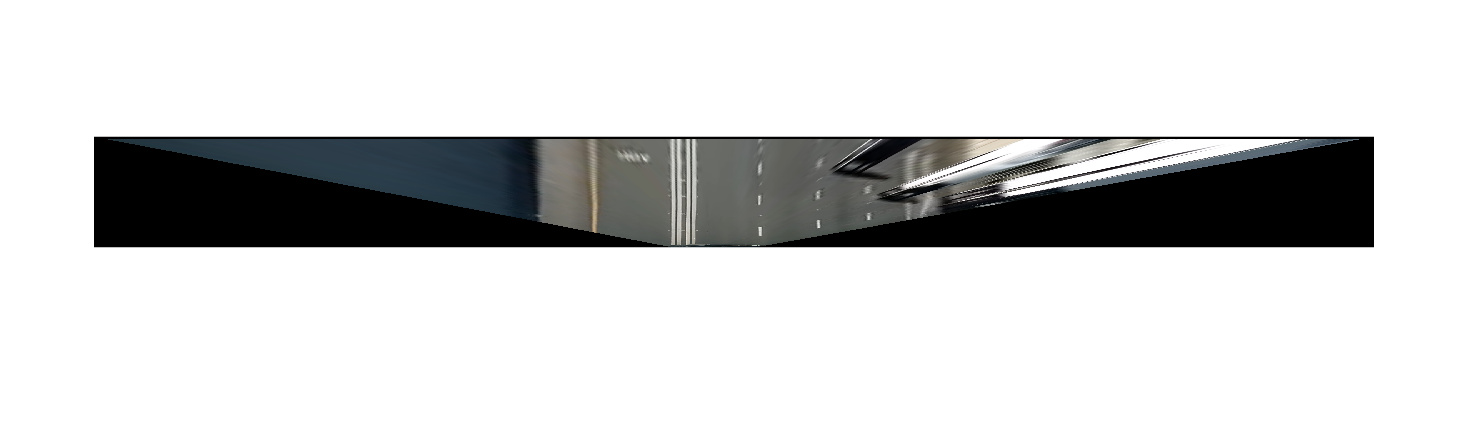

% Refence Points from Court Model
A = [320 0]'; 
B = [1280-320 0]';
C = [1280-320 720]';
D = [320 720]';
pin = [pa pb pc pd]; % 2xN matrix of inputs
pout = [A B C D]; % 2xN matrix of output
H = fitgeotrans(pin',pout', 'projective');
[Iwarp, ref] = imwarp(img,H);
imshow(Iwarp)

straight_img = Iwarp(1:720,5020-1280:5020+1280,:);
straight_img = imresize(straight_img, [720 1280]);
imshow(straight_img)
imwrite(straight_img, "straight_imgs\straight_img5q.jpg")